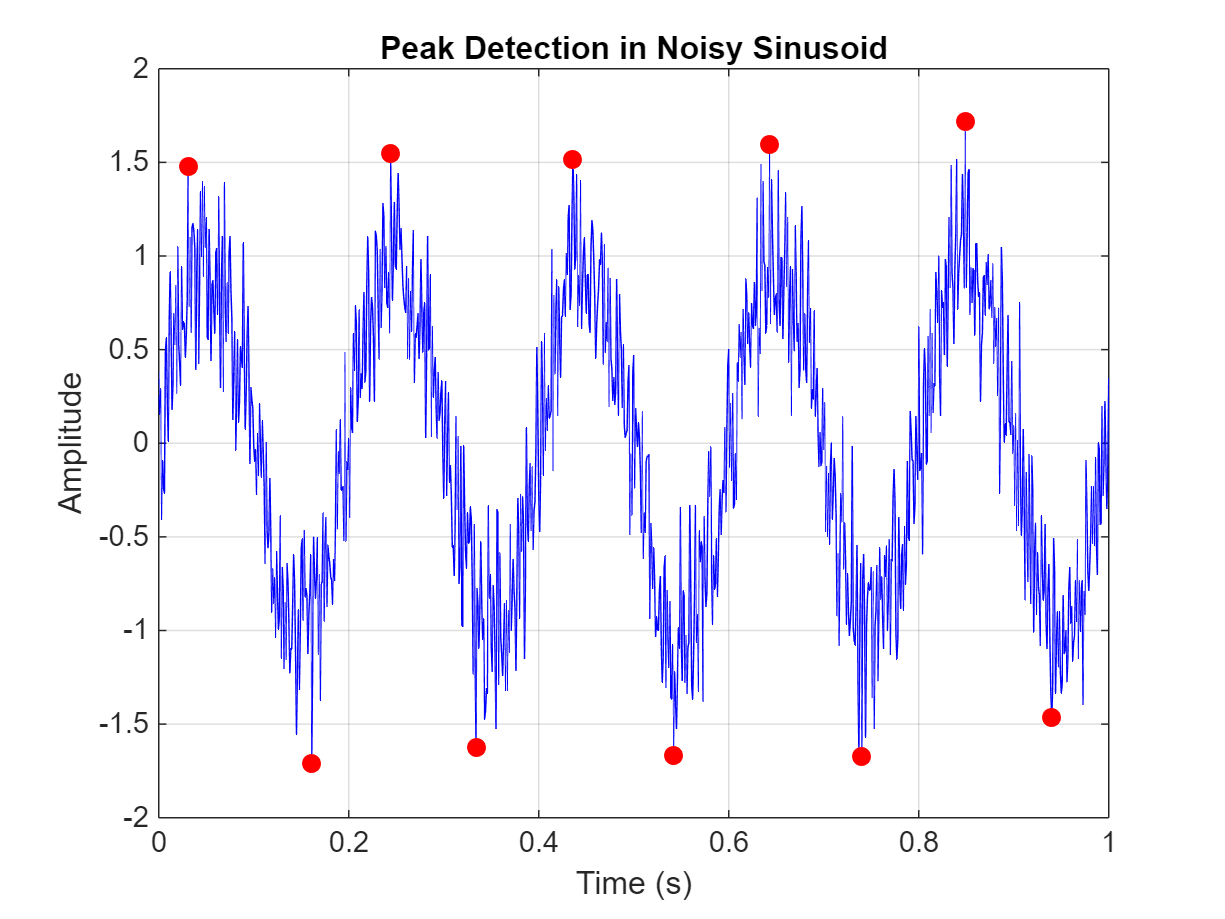

% Generate a noisy sinusoidal signal
fs = 1000;                % Sampling frequency (Hz)
t = 0:1/fs:1;             % Time vector (1 second)
x = sin(2*pi*5*t) + 0.3*randn(size(t));  % 5 Hz sine + noise

% Find peaks
[pks, locs_peaks] = findpeaks(x, t, ...
    'MinPeakProminence', 0.8, ...   % Ignore small peaks (noise)
    'MinPeakDistance', 0.17);        % Enforce minimum spacing (seconds)
% Find valleys
[valleys, locs_valleys] = findpeaks(-x, t, ...
    'MinPeakProminence', 0.8, ...   % Ignore small peaks (noise)
    'MinPeakDistance', 0.17);        % Enforce minimum spacing (seconds)
valleys=-valleys;
% Plot results
figure;
plot(t, x, 'b'); hold on;
plot(locs_peaks, pks, 'ro', 'MarkerFaceColor', 'r');
plot(locs_valleys, valleys, 'ro', 'MarkerFaceColor', 'r');

xlabel('Time (s)');
ylabel('Amplitude');
title('Peak Detection in Noisy Sinusoid');
grid on;